clc;
clear all
close all

Parameters


### Transition matrix

**Description**: The transition matrix evaluates the probability of producing a daughter cell of a different type than the mother cell. The rows of the cell indicates the parent cell type, and the columns the daughter cell type. The cell type follows the `plasmid_labels` array.

For instance, the position $T(16,16)$ indicates the probability that the parent cell is of type $16$ (Prototrophic cell HLMU) and it produces a daughter cell of the same type $16$. The position $T(16,15)$ indicates the probability of a parent cell of type $16$ to produce a daughter cell of type $15$ (Auxotrophic cell: HLU).

% Transition Matrix T 16 x 16
% This transition matrix evaluates the probability of having a new
% daughter cell of type (j) from the parent cell of type (i)
T = zeros(16,16);
for i = 1:16 %loop in the type of parent cell
    for j = 1:16 %loop in the type of daughter cell
        prob=1; %restart the calculations
        for plasmid = 1:4 %loop in the number of plasmids the daughter cell defer from the parent cell
            if (states(i,plasmid) == 1 && states(j,plasmid) == 0)
                prob = prob*p_s;
            % elsif (states(i,plasmid) == 0 && states(j,plasmid) == 0)
            %     prob = prob*(1-p_s);
            elseif (states(i,plasmid) == 0 && states(j,plasmid) == 1)
                prob = 0; % cannot regain plasmid
                break;
            end
        end
        T(i,j) = prob;
    end
    if(i>1)
        T(i,i) = 1-sum(T(i,1:(i-1)));%evaluates the probability for the duagther cell to be similar to the parent cell
    end
end

### Generation Matrix

**Description:** This matrix stores per row the generation where a daughter cell is produced with a different type other than the parent cell type. The rows of the cell indicates the parent cell type, and the columns the daughter cell type. The cell type follows the `plasmid_labels` array.

For instance, $G(16,16)=26$ indicates that at generation $26$ the cell type $16$ starts producing a different cell type than the parent cell $16$. The new daughter cell-type produced is found with the transition matrix $T$. As the values in the rows of the matrix $T$ decreases from right to left, then the new daugther cell follows the type of the next non-zero value to the left of $16$; in this case is cell type $15$.

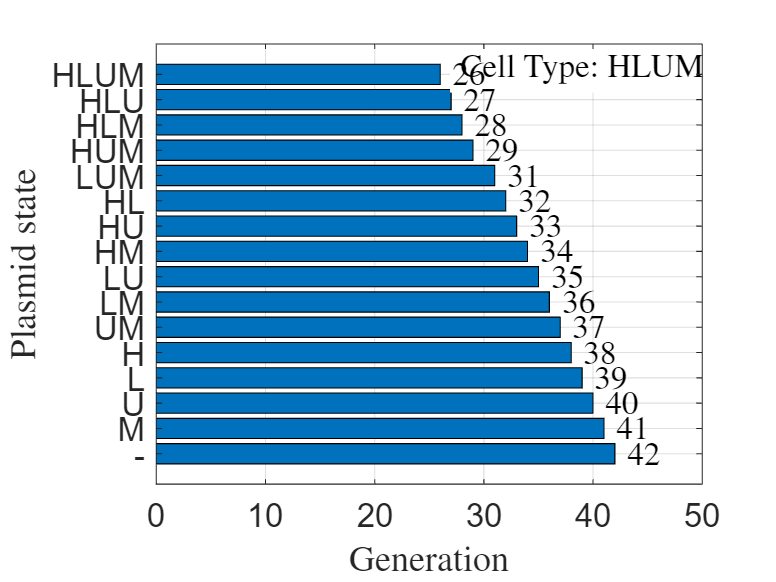

%Description: This matrix stores the first-time generation where the cell
%type produce a cell of a different type with the highest probability
%for instance when G displays the value 26 at coordinates (16,16), it means
%that the cell 16 replicates the cell 16 for 26 generations. When G(16,15)
%displays 27 it means that the daughter generations start to produce cell
%type 15 more likely.
G = zeros(16,16);
gen_temp=0;%stores the previous generation where a change in the daughter cell changes
%loop in the number of cell types
for i_state=1:16-1
    gen_temp=0;%stores the previous generation where a change in the daughter cell changes

    %start on the last row within the T matrix
    i_state_rev=16-i_state+1;
    for j_state=1:16-1
        %start on the last column within the T matrix
        j_state_rev=16-j_state+1;
        if(i_state_rev==15 && j_state_rev==15)
            p=1;
        end
        %loop in the number of generations
        %look for the first element from righ to left larger than zero
        idx = find(T(i_state_rev,1:j_state_rev-1) > 0, 1, 'last');
        for gen=1:num_generations
            if(T(i_state_rev,j_state_rev)^gen<T(i_state_rev,idx) && T(i_state_rev,j_state_rev)~=0)
                G(i_state_rev,j_state_rev)=gen-1+gen_temp;
                %update gen_temp
                gen_temp=G(i_state_rev,j_state_rev);
                break;
            end
        end
        %condition to stop the calculations
        if(gen_temp>num_generations)
            break;
        end
    end
    %updating the first item in the line
    G(i_state_rev,1)=gen_temp+1;
    %condition to stop the calculations
    if(gen_temp>num_generations)
        break;
    end
    
end

%updating the element (1,1) of G
G(1,1)=max(G(16,:));

barh(G(16,:)); 
grid on;

% Set Y-ticks to match plasmid labels
set(gca, 'YTick', 1:16, 'YTickLabel', plasmid_labels);
ytickangle(0); % Keep labels horizontal

xlabel('Generation', 'Interpreter','latex');
ylabel('Plasmid state', 'Interpreter','latex');
set(gca, 'FontSize', font);

% Add annotation text (e.g., overall cell type info) at an adjusted position
x_limits = xlim;
y_limits = ylim;
x_pos = x_limits(1) + 0.55 * diff(x_limits);
y_pos = y_limits(2) - 0.05 * diff(y_limits);

text(x_pos, y_pos, ...
    strjoin(["Cell Type:", plasmid_labels(end)], ' '), ...
    'Interpreter','latex', 'BackgroundColor','w','FontSize',font);

% Now, add generation numbers at the end of each horizontal bar.
vals = G(16,:);  % The values (bar lengths) for each bar
numBars = numel(vals);
offset = 0.02 * max(vals);  % Small offset to the right of each bar

for k = 1:numBars
    % In a horizontal bar plot, the center of the k-th bar is at y = k.
    x_text = vals(k) + offset;  % Place the label just to the right of the bar
    y_text = k;
    generationLabel = sprintf('%d', vals(k));
    text(x_text, y_text, generationLabel, 'HorizontalAlignment', 'left', ...
         'VerticalAlignment', 'middle', 'FontSize', font, 'Interpreter','latex');
end

### Evaluating the number of cells per generation

number_cells_gen=zeros(16,num_generations);
number_cells_gen(16,1)=1;%initial condition, the mother cell is prototrophic
for i_cell=1:16
    %start on the last row within the G matrix
    i_cell_rev=16-i_cell+1;
   
    %looking for the indexes in the row of the matrix G where the values
    %are nonzero.
    idx = find(G(i_cell_rev,(1:end)) ~= 0);
    i_idx=length(idx);%index to start reading idx from left to right
    num_transf_cells=0;%number of daughter cells different from the parent cell
    flag=0;%set to 1 whenever a daughter cell start to be different from the parent cell
    %looking for the first nonzero element in the row of G, this account
    %for the cells already there comming from the parent row below
    G_ini=find(number_cells_gen(i_cell_rev,:),1,'first');
    for gen=2:num_generations
        %the population stop growing
        if (num_transf_cells>number_cells_gen(i_cell_rev,gen-1))
            number_cells_gen(i_cell_rev,gen)=number_cells_gen(i_cell_rev,gen-1);
        %population growth except for the different type daughter cells
        
        % elseif(gen~=G(i_cell_rev,i_idx)+1)
        elseif(gen~=G(i_cell_rev,idx(i_idx))+G_ini)
            number_cells_gen(i_cell_rev,gen)=number_cells_gen(i_cell_rev,gen-1)+...%previous population
                                            (number_cells_gen(i_cell_rev,gen-1)-num_transf_cells)+...%population growth
                                            number_cells_gen(i_cell_rev,gen);%accounts for the cells introduced by the previous rows
        else %the population duplicates except for the number of new daughter cells of a different type
            number_cells_gen(i_cell_rev,gen)=2*number_cells_gen(i_cell_rev,gen-1)-(num_transf_cells+1);
            %update the index in the matrix G
            i_idx=i_idx-1;
            flag=1;
        end
        %evaluating when different daughter cells are coming from the current
        %parent cell
        if (flag==1)
            num_transf_cells=num_transf_cells+1;
            %update the number of cells in the corresponding daughter row
            if(i_idx==0)
                i_idx=1;
            end
            number_cells_gen(idx(i_idx),gen:end)=number_cells_gen(idx(i_idx),gen:end)+1;
        end
        % %for testing
        % if(gen==64 && i_cell_rev==14)
        %     test=1;
        % end
    end
end

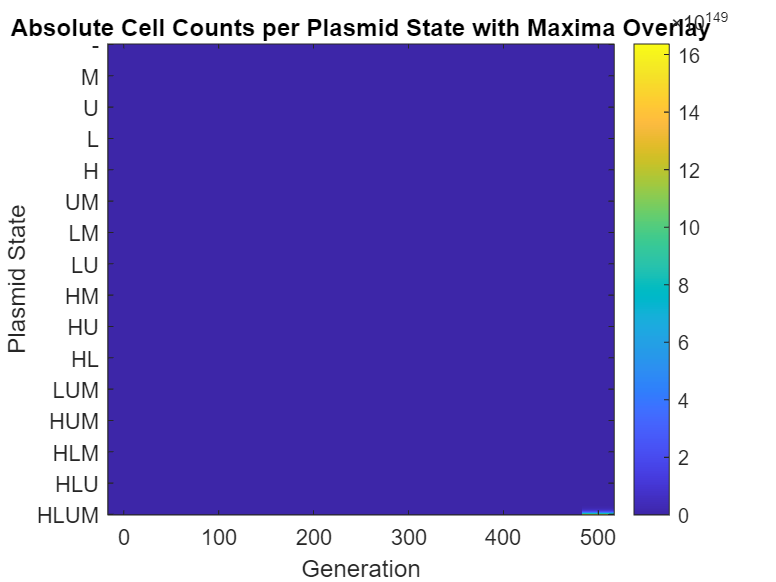

figure;
imagesc(0:gen,1:16,number_cells_gen'); hold on

colorbar;
% hold on;
% plot(0:num_generations, max_indices, '-w','LineWidth',2);
% hold off;
xlabel('Generation');
ylabel('Plasmid State');
title('Absolute Cell Counts per Plasmid State with Maxima Overlay');
set(gca,'YTick',1:16,'YTickLabel',plasmid_labels);

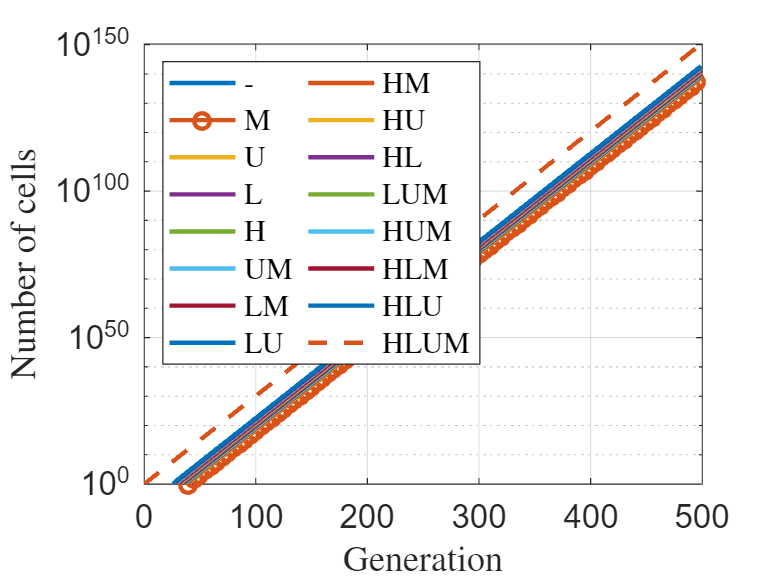

figure;

semilogy(0:gen-1,number_cells_gen(1,:),"LineWidth",2); grid on; hold on;
semilogy(0:gen-1,number_cells_gen(2,:),'-o',"LineWidth",2,...
        'MarkerSize',7,'MarkerIndices',1:5:num_generations);

for i=3:15
    semilogy(0:gen-1,number_cells_gen(i,:),"LineWidth",2);
end

semilogy(0:gen-1,number_cells_gen(i+1,:),'--',"LineWidth",2); hold off


xlabel('Generation','Interpreter','latex');
ylabel('Number of cells','Interpreter','latex');
legend({plasmid_labels{:}},...
    'Location','northwest','NumColumns',2,'Interpreter',"latex");
set(gca,'FontSize',font)

concentration=zeros(16,gen)

concentration =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0   

for gen=1:num_generations
    concentration(:,gen)=number_cells_gen(:,gen)./sum(number_cells_gen(:,gen));
end

gen=70;
number_cells_gen(16,gen)/sum(number_cells_gen(1:15,gen))

ans = 1.6777e+07

### References

[1] Kate Campbell, Jakob Vowinckel, Michael Mülleder, Silke Malmsheimer, Nicola Lawrence, Enrica Calvani, Leonor Miller-Fleming, Mohammad T Alam, Stefan Christen, Markus A Keller, Markus Ralser (2015) Self-establishing communities enable cooperative metabolite exchange in a eukaryote eLife 4:e09943